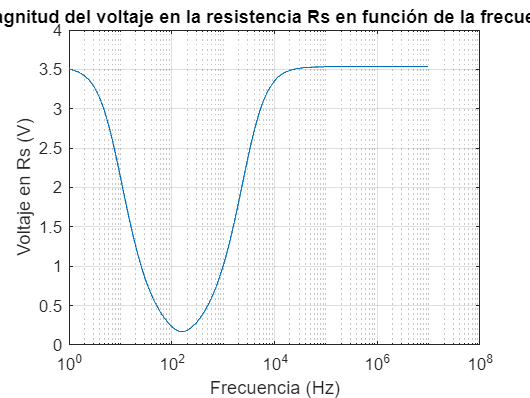

E = 5;
Erms = 5/sqrt(2);
Rs = 5;
C = 10e-6;
L = 0.1;
R = 100;
frequencies = logspace(0, 7, 1000);  % Rango de frecuencias de 1 Hz a 10 MHz

% Inicializar un vector para almacenar las magnitudes de VRS
VRS_magnitudes = zeros(size(frequencies));

for i = 1:length(frequencies)
    frequency = frequencies(i);
    
    % Impedancias de los componentes
    Xc = 1/(2*pi*frequency*C)*-1j;  % Impedancia del condensador
    Xl = 2*pi*frequency*L*1j;       % Impedancia del inductor
    
    % Impedancia total del circuito RLC en paralelo
    ZRLC = 1/((1/R) + (1/Xl) + (1/Xc));
    
    % Cálculo del voltaje en Rs usando un divisor de voltaje
    VRS = Erms * (Rs / (Rs + ZRLC));
    
    % Guardar la magnitud del voltaje en Rs
    VRS_magnitudes(i) = abs(VRS);
end

% Graficar la magnitud del voltaje en Rs en función de la frecuencia
figure;
semilogx(frequencies, VRS_magnitudes);
title('Magnitud del voltaje en la resistencia Rs en función de la frecuencia');
xlabel('Frecuencia (Hz)');
ylabel('Voltaje en Rs (V)');
grid on;